## Exercici: Segmenteu els grans de cafè

Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna 

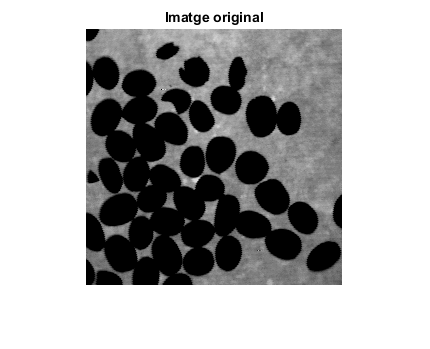

im = imread('cafe.tif');
figure, imshow(im),title('Imatge original')

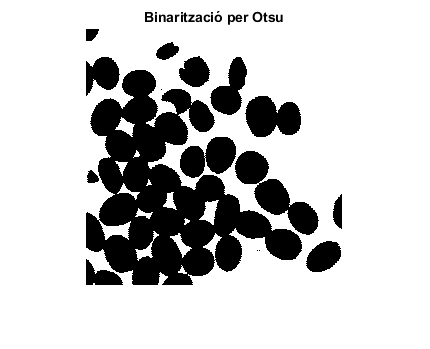


bw = im2bw(im,graythresh(im));
figure,imshow(bw), title('Binarització per Otsu')

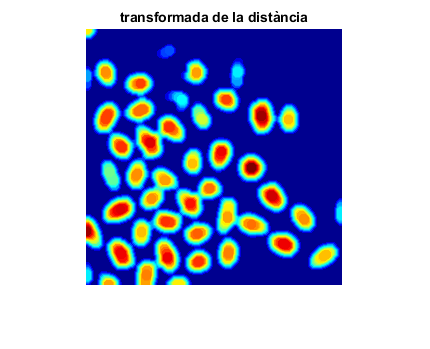


d = bwdist(im);

ee = strel('disk', 5);
op = imopen(d,ee);

figure, imshow(op,[]), colormap('jet'), title('transformada de la distància')

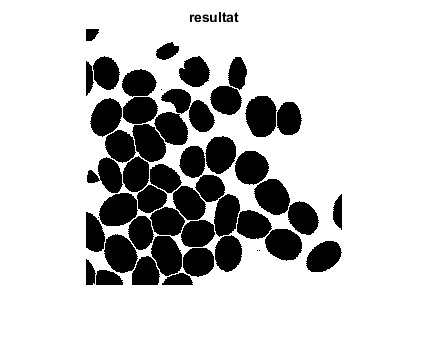

segm = watershed(-op);

res = im;
res(segm==0)=255;
res = imbinarize(res, graythresh(res));
figure,imshow(res), title('resultat')